# Problem 15-48

clear
syms r a b g real positive

(a) Plot swing period versus distance r

T = 2*pi*sqrt(((a^2+b^2)/12+r^2)/(g*r))

$$T = \frac{2\,\pi \,\sqrt{\frac{a^{2}}{12}+\frac{b^{2}}{12}+r^{2}}}{\sqrt{g}\,\sqrt{r}}$$

Tn = subs(T,[a,b,g],[0.35,0.45,9.81])

$$Tn = \frac{20\,\pi \,\sqrt{981}\,\sqrt{r^{2}+\frac{13}{480}}}{981\,\sqrt{r}}$$

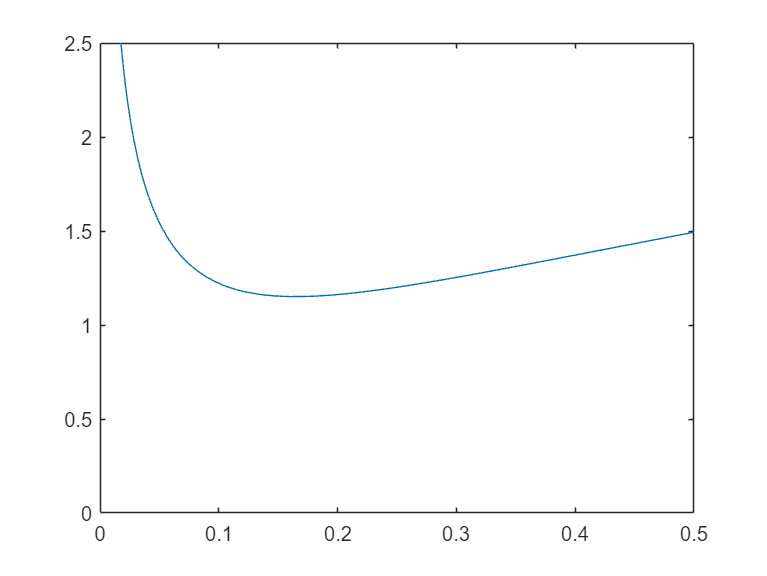

fplot(Tn,[0 0.5]), ylim([0 2.5])

(b) For what value of r does that minimum occur?

dTdr = simplify(diff(T,r))

$$dTdr = -\frac{\pi \,\sqrt{3}\,\left(a^{2}+b^{2}-12\,r^{2}\right)}{6\,\sqrt{g}\,r^{3/2}\,\sqrt{a^{2}+b^{2}+12\,r^{2}}}$$

rmin = solve(dTdr==0,r)

$$rmin = \frac{\sqrt{3}\,\sqrt{a^{2}+b^{2}}}{6}$$

rmin_num = vpa(subs(rmin,[a,b],[0.35,0.45]),3)

$$rmin\_num = 0.165$$

(c) The curve of such points is a circle around the center of mass